# Control of VEC Using Nonlinear Model Predictive Control

clear all; close all;clc;
nx = 6;
ny = 6;
nu = 2;
nlobj = nlmpc(nx, ny, nu);

In standard cost function, zero weights are applied by default to one or more OVs because there are fewer MVs than OVs.


nlobj.Model.StateFcn = "VECStateFcn";
% nlobj.Jacobian.StateFcn = @VECStateJacobianFcn;
% rng(0)
% validateFcns(nlobj,rand(nx,1),rand(nu,1));
Duration = 1000;
Ts = .02;
p = 4;
c = 4; n=2;
nlobj.Ts = Ts;
nlobj.PredictionHorizon = p;
nlobj.ControlHorizon = c;
nlobj.MV = struct( ...
    Min={-pi/6;-pi/6}, ...
    Max={pi/6;pi/6}, ...
    RateMin={-.2;-.2}, ...
    RateMax={.2;.2} ...
    );
nlobj.Weights.OutputVariables = [10000 0 10000 0 100 100];
q = [1 1];
nlobj.Weights.ManipulatedVariables = [1 1];
r = [100 1];
nlobj.Weights.ManipulatedVariablesRate = [1 1];

## Closed-Loop Simulation

% Specify the initial conditions
% Nominal control that keeps the VEC floating
nloptions = nlmpcmoveopt;
nloptions.MVTarget = [0 0]; 
mv = nloptions.MVTarget;
kkk=1;

Simulate the closed-loop system using the `nlmpcmove` function, specifying simulation options using an `nlmpcmove` object.

## **OUTER LOOP**


for kk=1:1
f =     (.01-(.001))*rand(1,1)+.001;
f=.001;
% loop1 = (16-(12))*rand(1,1)+12;
% loop2 = (12-(8))*rand(1,1)+8;
% loop3 = (2.1-(1.9))*rand(1,1)+1.9;
% amp = (.1-(.001))*rand(1,1)+.001;
% org = (500-(0))*rand(1,1)+(0);
% rad = (1000-(100))*rand(1,1)+(100);

t = 0:Ts:Duration;
yref = VECReferenceTrajectory(Ts,t,f,14,10,2,.1,0,100);
xHistory = yref(1,:);  
lastMV = mv; uHistory = lastMV;
uk_pred = mv; 
nloptions.MV0 = zeros(p,n);    
hbar = waitbar(0,'Simulation Progress'); 

**inner loop**

 for k = 1:(Duration/Ts)
    % Set references for previewing
    t = linspace(k*Ts, (k+p-1)*Ts,p);
yref = VECReferenceTrajectory(Ts,t,f,14,10,2,.1,0,100);
    % Compute the control moves with reference previewing.
    xk = xHistory(k,:);

**calculate the first control input of the current cycle based on fault states**

    uk_pred = nloptions.MV0(2:end,:) ;
    rrr= (.1-(-.1))*rand(1,2)+(-.1); 
    xk1 =   [xk(5) xk(6)] ;
    xxk1 = xk1 + rrr; 
    xxk =  [xk(1:4) xxk1(1:2)];
    Beta(kkk,:) =  max(calcFeature(xxk1, xk1, q)); 
    
    [uk,nloptions,info] = nlmpcmove(nlobj,xxk,lastMV,yref,[],nloptions);

claculate BSM 

    ukk = nloptions.MV0(1:end-1,:) ;
    BSM(kkk,:) = max(max(abs(ukk - uk_pred)./[.4,.4]));  kkk=kkk+1;

  Update states

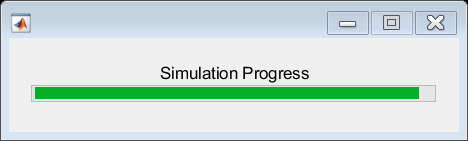

Error using horzcat
Requested 6x355668400 (15.9GB) array exceeds maximum array size preference (15.9GB). This might cause MATLAB to become unresponsive.

Error in ode45 (line 484)
          yout = [yout, zeros(neq,chunk,dataType)]; %#ok<AGROW>

Error in getstates (line 3)
    [TOUT,YOUT] = ode45(ODEFUN,[0 Ts], xk);

<

    xk = getstates(xxk,uk,Ts);
    uHistory(k+1,:) = uk';
    duHistory(k,:) = abs(uHistory(k+1,:) - uHistory(k,:)) ;
    lastMV = uk;
    xHistory(k+1,:) = xk;
    waitbar(k*Ts/Duration,hbar);
 end
 close all;
 plotVECTrajectory;
 close(hbar);
 kk
end

a = [Beta,BSM];
figure,plot(a);legend('feature','BSM');
b = sortrows(a,1);
a2 = reshape(b(:,2),length(BSM)/10,[]);
figure,boxplot(a2);
str ='\Delta^{max}_c' ;
ylabel(str,'interpreter','tex','FontSize',20)
xlabel('Percentiles','FontSize',16)

function [Beta] =  calcFeature(xxk,xk,q)
    Beta = (xxk - xk).^2 .*q ;
end